
% Coda-Forno Mateo :  20266263  

% Paramètres
N = 20;                % Taille de la matrice
alpha = 2;             
beta = -1;             
x_exact = ones(N, 1);  % Solution exacte
precision = 1e-4;        % Critère d'arrêt
itermax = 1e5;         
x0 = zeros(N, 1);      % Solution initiale

% Matrice A tridiagonale
A = diag(alpha * ones(N, 1)) + diag(beta * ones(N-1, 1), 1) + diag(beta * ones(N-1, 1), -1);
b = A * x_exact;      

% Matrice d'itération Jacobi
D = diag(diag(A));
D_inv = diag(1 ./ diag(A));
L_plus_U = A - D;
TJ = D_inv * L_plus_U;

% Calcul du rayon spectral ρ(TJ)
vals_propres = eig(TJ);
rho_TJ = max(abs(vals_propres));
disp(['ρ(TJ) = ', num2str(rho_TJ)]);

ρ(TJ) = 0.98883



% Initialisation pour la méthode de Jacobi
xnew = x0;
errors = [];  % Stockage des erreurs
errors_ratio = [];  % Stockage des rapports d'erreurs

for it = 1:itermax
    % Mise à jour de x
    xnew = D_inv * (b - L_plus_U * x0);
    
    % Calcul de l'erreur
    erreur = norm(xnew - x_exact, 2);
    errors(end + 1) = erreur;  % Stockage de l'erreur actuelle
    
    % Critère d'arrêt
    if erreur < precision
        break;
    end
    
    % Calcul du rapport des erreurs successives (à partir de la 2e itération)
    if it > 1
        errors_ratio(end + 1) = errors(end) / errors(end-1);
        % disp(errors_ratio)
    end
    
    % Mise à jour pour la prochaine itération
    x0 = xnew;
end

% Résultats finaux
disp(['Nombre d''itérations : ', num2str(it)]);

Nombre d'itérations : 947


disp(['Erreur finale : ', num2str(errors(end))]);

Erreur finale : 9.8906e-05



% Vérification du rapport des erreurs successives
disp(['Rapport des erreurs à la dernière itération : ', num2str(errors_ratio(end))]);

Rapport des erreurs à la dernière itération : 0.98883


Combien vaut k? Est-ce que le rapport ke (j+1)k2/ke (j)k2 ≈ ρ(TJ ) pour j(≤ k −1) suffisamment grand (comme prédit sur la page 94 des notes de cours)?

On a k qui vaut 947 avec une erreur finale = 9.8906e-05, et le rapport d'erreur pour les iterations converge vers  `0.98883 `on a donc bien le resultat montrer a la page 94 du cours qui disait : lim k→∞ ke (k)k ke (k+1)k = 1 |λ1| = 1 ρ(T) car ρ(TJ) = 0.98883 . Avec  ρ(TJ) < 1 ce qui implique, comme determiner a la question 3a une convergence de la methode de Jacobi pour alpha = 2 et B = -1. 

% Question 2:

x0 = zeros(N, 1);      % Solution initiale

% Matrice d'itération de Gauss-Seidel
TG = -inv(D + L) * U;   % Matrice d'itération

% Calcul du rayon spectral ρ(TG)
vals_propres = eig(TG);
rho_TG = max(abs(vals_propres));
disp(['ρ(TGS) = ', num2str(rho_TG)]);

ρ(TGS) = 0.97779



% Méthode de Gauss-Seidel
xnew = x0;
errors = [];            
errors_ratio = [];      

for it = 1:itermax
    for i = 1:N
        % Mise à jour de x (Gauss-Seidel)
        xnew(i) = (b(i) - A(i, 1:i-1) * xnew(1:i-1) - A(i, i+1:N) * x0(i+1:N)) / A(i, i);
    end
    
    % Calcul de l'erreur
    erreur = norm(xnew - x_exact, 2);
    errors(end + 1) = erreur;  % Stockage de l'erreur actuelle
    
    % Critère d'arrêt
    if erreur < precision
        break;
    end
    
    % Calcul du rapport des erreurs successives (à partir de la 2e itération)
    if it > 1
        errors_ratio(end + 1) = errors(end) / errors(end-1);
    end
    
    % Mise à jour pour la prochaine itération
    x0 = xnew;
end

% Résultats finaux
disp(['Nombre d''itérations : ', num2str(it)]);

Nombre d'itérations : 474


disp(['Erreur finale : ', num2str(errors(end))]);

Erreur finale : 9.9091e-05



% Vérification du rapport des erreurs successives
disp(['Rapport des erreurs à la dernière itération : ', num2str(errors_ratio(end))]);

Rapport des erreurs à la dernière itération : 0.97779


    Combien vaut k? Est-ce que le rapport ke (j+1)k2/ke (j)k2 ≈ ρ(TJ ) 2 pour j(≤ k −1) suffisamment grand (comme prédit sur la page 94 des notes de cours)?

    On a k qui vaut 474, avec un rapport qui converge vers `0.97779. Etant donne que p(Tj)**2 ~= `0.9777847689 on a bien le resultat attendu etant que le rapport d'erreur ~= p(Tj)**2




% Question 3:

x0 = zeros(N, 1);  % Solution initiale

% Critères d'arrêt
itermax = 1e5;  
tol = 1e-6;  

% Paramètres de SOR
omega_range = 1.65:0.002:1.79;  % Plage de valeurs pour omega
iterations = zeros(size(omega_range));  % Stockage des itérations pour chaque omega

% Boucle sur les valeurs de omega
for idx = 1:length(omega_range)
    omega = omega_range(idx);  % Valeur actuelle de omega
    xnew = x0;  % Réinitialiser xnew
    for it = 1:itermax
        for i = 1:N
            % Mise à jour de la solution xnew
            xnew(i) = xnew(i) + omega * (b(i) - A(i, :) * xnew) / A(i, i);
        end
        
        % Calcul de l'erreur
        erreur = norm(xnew - x_exact);
        % Vérification du critère d'arrêt
        if erreur < tol
            iterations(idx) = it;  % on enregistre le nombre d'itérations pour ce omega
            break;
        end
    end
end


% Trouver omega optimal : celui avec le moins d'itérations
[~, opt_idx] = min(iterations);
omega_opt = omega_range(opt_idx);


disp(['ω optimal : ', num2str(omega_opt)]);

ω optimal : 1.744


disp(['Nombre minimal d''itérations : ', num2str(iterations(opt_idx))]);

Nombre minimal d'itérations : 57


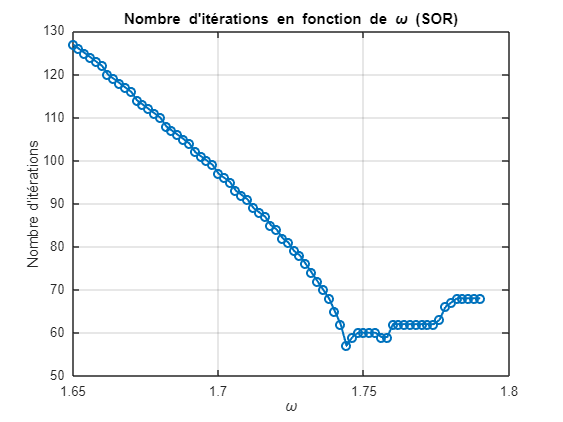


% Graphique
figure;
plot(omega_range, iterations, '-o', 'LineWidth', 1.5);
xlabel('\omega');
ylabel('Nombre d''itérations');
title('Nombre d''itérations en fonction de \omega (SOR)');
grid on;

Comparer votre estimation de ωopt avec la valeur donnée dans l’énoncé du théorème:

Le theoreme dit que dans le cas d une matrice tridiagonal le choix optimal ωopt du facteur de relaxation ω est donné par ωopt = 2 / (1+ sqrt(1−[ρ(TJ )]2) ). 

Dans notre cas on a ρ(TJ) = 0.98883 => 2 / (1+ sqrt(1−[ρ(TJ )]2) ) ~= 1.74057170729. 

On a trouver via calcule numerique que w opt ~= 1,744 ; ainsi la valeur calcule numeriquement coincide avec la valeur determiner par le theoreme avec ici une erreur de 1*10-3.


% Question 4:
L = tril(A, -1);

% Calcul de Tωopt pour la méthode SOR
T_omega_opt = inv(D) * ((omega_opt * L) + ((1 - omega_opt) * D));

% Calcul des valeurs propres de Tωopt
vals_propres = eig(T_omega_opt);  

% Rayon spectral:
rho_T_omega_opt = max(abs(vals_propres));

% Vérification de la relation du theoreme:
omega_moins_1 = omega_opt - 1;

disp(['Le rayon spectral de Tωopt est : ', num2str(rho_T_omega_opt)]);

Le rayon spectral de Tωopt est : 0.744


disp(['ω_opt - 1 est : ', num2str(omega_minus_1)]);

ω_opt - 1 est : 0.744


disp(['La différence est : ', num2str(rho_T_omega_opt - omega_moins_1)]);

La différence est : 0
